clear;

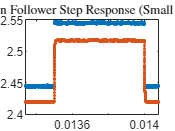

% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 3);

% Specify range and delimiter
opts.DataLines = [26, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Time_s_", "Channel1_V_", "Channel2_V_"];
opts.VariableTypes = ["double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
small_amplitude3 = readtable("C:\Users\lhunter\base\circuits_labs\Lab7\Experiment3\/small_amplitude.csv", opts);

% Convert to output type
t = small_amplitude3.Time_s_;
Vout = small_amplitude3.Channel1_V_;
Vin = small_amplitude3.Channel2_V_;

% Clear temporary variables
clear  small_amplitude3

% Clear temporary variables
clear opts
% plot(t(1000:3000),Vin(1000:3000),'.');
% hold on;
% plot(t(1000:3000),Vout(1000:3000),'.');
% title("Unity-Gain Follower Step Response (Small Amplitude, Rise)","Interpreter","latex");
% legend("Input Wave","Output Wave","Interpreter","latex","Location","best");
% hold off;
% 
% plot(t(6000:8000),Vin(6000:8000),'.');
% hold on;
% plot(t(6000:8000),Vout(6000:8000),'.');
% title("Unity-Gain Follower Step Response (Small Amplitude, Fall)","Interpreter","latex");
% legend("Input Wave","Output Wave","Interpreter","latex","Location","best");
% hold off;

plot(t,Vin,'.');
hold on;
plot(t,Vout,'.');
title("Unity-Gain Follower Step Response (Small Amplitude, $50mV$)","Interpreter","latex");

legend("Input Wave","Output Wave","Interpreter","latex","Location","best");

Error using legend
Unable to set the 'Title' property of class 'Legend' because it is read-only.

xlabel("Time ($s$)","Interpreter","latex");
ylabel("Voltage ($V$)","Interpreter","latex")
grid on;
hold off;



clear;

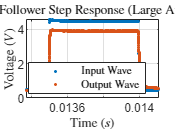

% Set up the Import Options and import the data
opts2 = delimitedTextImportOptions("NumVariables", 3);

% Specify range and delimiter
opts2.DataLines = [26, Inf];
opts2.Delimiter = ",";

% Specify column names and types
opts2.VariableNames = ["Time_s_", "Channel1_V_", "Channel2_V_"];
opts2.VariableTypes = ["double", "double", "double"];

% Specify file level properties
opts2.ExtraColumnsRule = "ignore";
opts2.EmptyLineRule = "read";

% Import the data
large_amplitude = readtable("C:\Users\lhunter\base\circuits_labs\Lab7\Experiment3\/large_amplitude.csv", opts2);

% Convert to output type
t = large_amplitude.Time_s_;
Vout = large_amplitude.Channel1_V_;
Vin = large_amplitude.Channel2_V_;

% Clear temporary variables
clear large_amplitude

% Clear temporary variables
clear opts2
plot(t,Vin,'.');
hold on;
plot(t,Vout,'.');
title("Unity-Gain Follower Step Response (Large Amplitude, $2V$)","Interpreter","latex");
legend("Input Wave","Output Wave","Interpreter","latex","Location","best");
xlabel("Time ($s$)","Interpreter","latex");
ylabel("Voltage ($V$)","Interpreter","latex")
grid on;
hold off;